# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.1 数值分析

#### 3.1.6 CVX工具箱求解凸优化问题

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

CVX工具箱下载地址：[Download CVX](http://cvxr.com/cvx/download/)

使用方法：下载压缩包之后解压到常用目录，命令行输入 cvx_setup 回车，无错误提示即可使用。

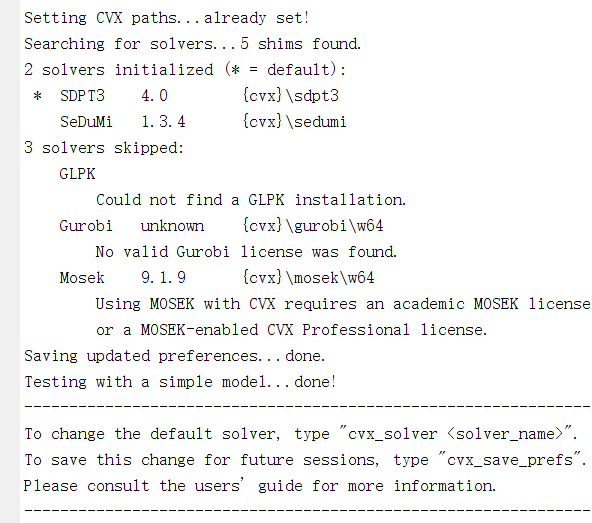

官网 Demo 检验：

clear;clc;
m = 20; 
n = 10; 
p = 4;
A = randn(m, n); 
b = randn(m, 1);
C = randn(p, n);
d = randn(p, 1); 
e = rand;
cvx_begin

此类型的变量不支持使用点进行索引。

出错 cvxprob (第 48 行)
    selected = cvx___.solvers.selected;

出错 cvx_begin (第 41 行)
assignin( 'caller', 'cvx_problem', cvxprob( varargin{:} ) );

    variable x(n)
    minimize( norm( A * x - b, 2 ) )
    subject to
        C * x == d
        norm( x, Inf ) <= e
cvx_end